# Exercici 7 de Laboratori

Sistema semi-automàtic per segmentar objectes

(Per Francesc Forn, Raúl Lumbreras i Martí Vall)

Obriu una imatge i comprovar que és una imatge RGB, fent servir la instrucció *size. *Mostrar la imatge per pantalla: *imshow.* 

I = imread("flor.png");
size(I,3)

ans = 3

imshow(I);

Obtenir del usuari el rectangle que emmarca l’objecte (fig. 4) que vol segmentar. Utilitzeu *rect = getrect. *Vigileu que la variable *rect* té el format (x, y, w, h); posició, amplada alçada (en lloc de fila i columna).

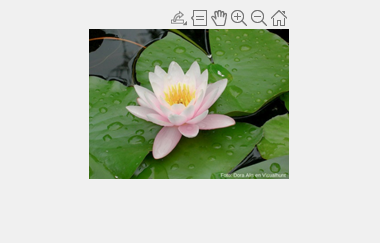

rect = getrect;

%Rectangle vermell?

Obtenir la imatge **HSV**: r*gb2hsv.* També es pot fer en altres espai de color com CIE Lab.

IHSV = rgb2hsv(I);

Preparem la taula pel *kmeans*. Cal construir una taula **O** amb tantes files com píxels i les següents columnes: [Hx Hy S V] On Hx Hy són les coordenades circulars 2D del hue.

Hx = cos(IHSV(:,:,1))/size(I,1);
Hy = sin(IHSV(:,:,1))/size(I,2);
S = IHSV(:,:,2);
V = IHSV(:,:,3);

O =  [reshape(Hx,[],1) reshape(Hy,[],1) reshape(S,[],1) reshape(V,[],1)];
      %Treure component x Treure component y del hue



Agrupem els colors en **k** classes amb kmeans i obtenim la classificació **C**, per exemple  k = 20;  **C**= kmeans(**O**,k);  

k = 20;
C = kmeans(O,k);

Si voleu veure el resultat (fig. 5) obtingut podeu executar el següent codi: IC = reshape(C,f,c); rgb = label2rgb(IC); imshow(rgb). Feu el mateix però amb els colors dels representants de cada classe obtinguda amb la funció Kmeans.

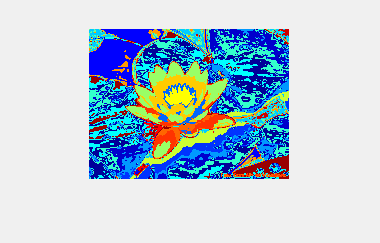

IC = reshape(C,[size(I,1)],[size(I,2)]);

rgb = label2rgb(IC);
imshow(rgb);

Ara la idea és veure quins colors cauen a dins del rectangle i quins fora. Per tal fi, construïm una imatge de valors booleans anomenada **MASK** de la mateixa mida que **I** amb els valors a zero si està fora del rectangle i 1 si està dins (fig 5). Nota: és molt fàcil construir-la amb una sola sentència, no us lieu a fer funcions de si un píxel està dins o fora d’un rectangle.

MASK = zeros(size(I,1),size(I,2));
MASK(rect(2):(rect(2)+rect(4)),rect(1):(rect(1)+rect(3))) = 1;

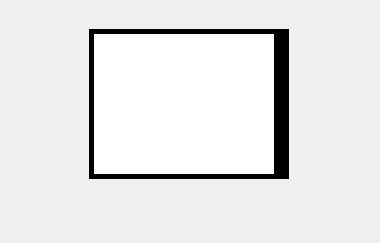

imshow(MASK);

Ara construïm un vector **H** que indicarà si un color cau dins del rectangle o no. Tal que H = [C, MASK(:)]; Observeu que H és una taula que indica si tal color C és dins o fora de la mascara.

H = [C, MASK(:)];

A continuació, comptem per a cada color de C quants píxels han caigut a fora i quants a dins. Guardem els resultats en dos arrays **Hist0** i **Hist1**. Evidentment, la mida de Hist0 i Hist1 ha de ser igual al nombre de classes *k*.

Hist0 = hist(H(H(:,2)==0),[1:k]); % H(:,2) == 0 retorna els valors fora del rectangle, 
                                  % H(H(:,2)==0) retorna els valors C de fora del rectangle
Hist1 = hist(H(H(:,2)==1),[1:k]); % El mateix pels punts de dins

Llavors decidim si un representant de color pertany a la figura que es vol segmentar comparant les seves aparicions dins i fora del rectangle. Guardem la decisió en un vector anomenat ***RES***. Quelcom com RES = Hist1 > Hist0;

RES = Hist1 > Hist0

RES = 1×20 logical array
   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1


Casi per últim, decidim per a cada  píxel de la matriu **H** si forma part de la figura o no utilitzant la informació que conté el vector **RES**. Guardem el resultat en un vector **M** i el mostrem per pantalla (fig 6).

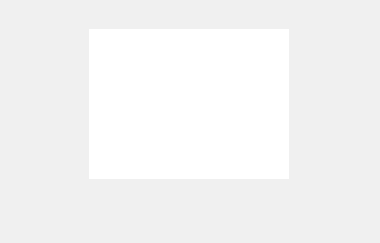

M = RES(H(:,1)); %Elements d'H que cauen tenen una k a 1 a RES
MFin = reshape(M,size(I,1),size(I,2));
imshow(MFin);

I per últim filtrem la imatge per a que el resultat no sigui tant sorollós i més compacte.

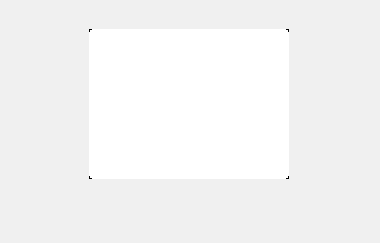

se = strel('disk',3);
MFinClean = medfilt2(MFin,[7 7]);
imshow(MFinClean)

b. Traieu o afegiu altres fons d’informació del píxel a les observacions del kmeans (columnes de la taula O) tals com posició o altres espais de color. Observeu el resultat obtinguts amb diferents imatges.

c. Experimenteu si es possible segmentar sense la finestra, suposant p.ex. que l’objecte està centrat en la imatge. Aquesta última tasca és opcional i totalment oberta per si voleu provar noves vies  (i es valorarà)...